# **주의**

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

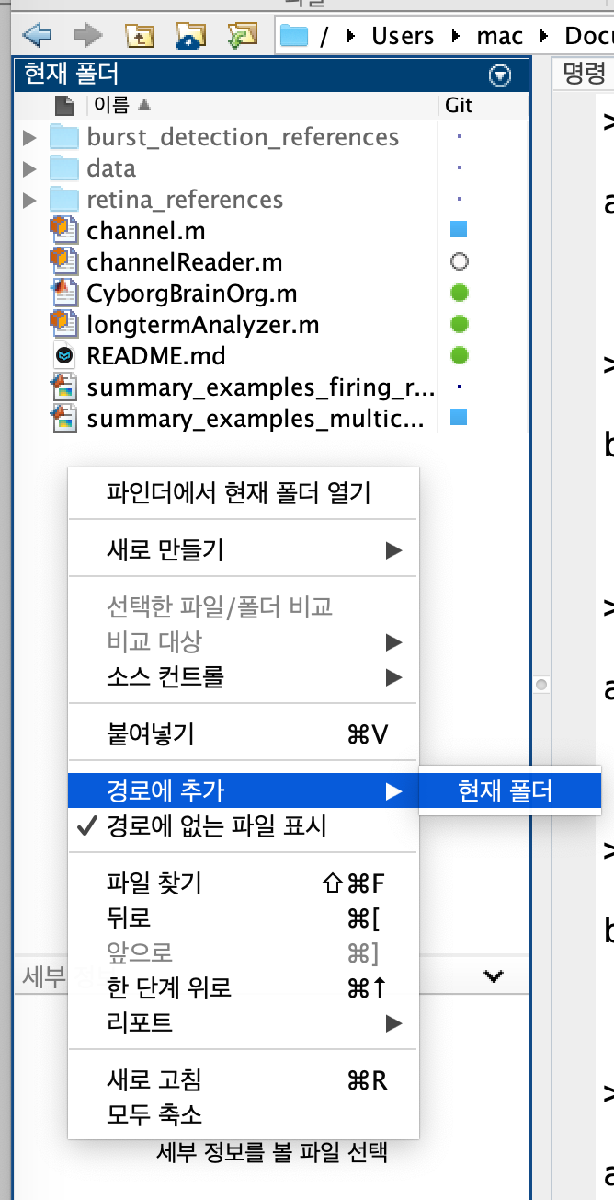

# **(1) Data 불러오기**

   순서:

- 데이터 파일 읽어오기 (기존과 동일)

- channel object 한번에 생성하기

- channel object 하나씩 생성하기

## 데이터 파일 읽어오기

이 부분은 예전과 똑같습니다.

reader = channelReader();
tic 
%                                 filename,        channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/1_singleunit wave.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 16 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16



toc % 코드 실행 시간 측정. 오래 걸림.

Elapsed time is 86.637082 seconds.


## channel object 한번에 생성하기

**(method) readManyMixedChannelsFromFile**

**paramter 1개**

- `organoid`: organoid 번호 (기존 함수에 있던 파라미터)

- `month: `month 번호 (기존 함수에 있던 파라미터)

- `LFP band`

- `SU band`

**output 2개**

- `channel dictionary`

다루는 brain region이 "visual"이라고 가정하겠습니다. channel들을 저장하고 있는 객체를 visual이라고 이름붙이겠습니다. 아래 코드를 실행하면 파일에 있는 채널을 다 불러오고 bandpass를 통해 LFP와 SU로 나누어 저장합니다. 실행에 시간이 좀 걸립니다.

visual = reader.readManyMixedChannelsFromFile(1,1, [0.1,300], [300,3000]);

Reading 16 mixed channels at once...

LFP:
channel number = 1
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 1
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

LFP:
channel number = 2
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 2
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

LFP:
channel number = 3
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 3
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

LFP:
channel number = 4
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152

개별 채널에 접근할 때는 아래와 같이 채널 번호, LFP/SU 여부를 따옴표 안에 입력합니다 (라벨링을 “brain region_channel번호_SU or LFP” 으로 하는 것과 비슷하게 구현하고자 했습니다). 이제 기존 파일에서 channel object를 가지고 하던 작업을 모두 수행할 수 있습니다.

visual("1, LFP")

ans =   channel with properties:

                              organoidNum: 1
                               channelNum: 1
                                    month: 1
                                       sf: 2.4414e+04
                                  msPerTs: 0.0410
                              nTimestamps: 565248
                                startTime: 0
                            endTimeApprox: 23.1525
                           durationApprox: 23.1525
                             originalTime: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e-04 6.9632e-04 7.3728e-04 … ]
                                        t: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e

## 한 channel object만 생성하기

채널 하나를 읽어오면 두 개의 channel object (LFP, SU)를 생성합니다. 각 channel object에는 아래와 같은 방법으로 접근합니다.

%                                        organoid, channel, month 
o1_ch8_m1 = reader.readMixedSingleChannelFromFile(1, 8, 1, [0.1,300], [300,3000]); %�*% 채널번호, LFP range, SU range를 수정합니다

LFP:
channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248

SU:
channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



o1_ch8_m1("LFP")

ans =   channel with properties:

                              organoidNum: 1
                               channelNum: 8
                                    month: 1
                                       sf: 2.4414e+04
                                  msPerTs: 0.0410
                              nTimestamps: 565248
                                startTime: 0
                            endTimeApprox: 23.1525
                           durationApprox: 23.1525
                             originalTime: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e-04 6.9632e-04 7.3728e-04 … ]
                                        t: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e

o1_ch8_m1("SU")

ans =   channel with properties:

                              organoidNum: 1
                               channelNum: 8
                                    month: 1
                                       sf: 2.4414e+04
                                  msPerTs: 0.0410
                              nTimestamps: 565248
                                startTime: 0
                            endTimeApprox: 23.1525
                           durationApprox: 23.1525
                             originalTime: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e-04 6.9632e-04 7.3728e-04 … ]
                                        t: [0 4.0960e-05 8.1920e-05 1.2288e-04 1.6384e-04 2.0480e-04 2.4576e-04 2.8672e-04 3.2768e-04 3.6864e-04 4.0960e-04 4.5056e-04 4.9152e-04 5.3248e-04 5.7344e-04 6.1440e-04 6.5536e

# (2) LFP의 band별 plot

**(method) getBand**

filtering 하는 frequency range 를 직접 지정해서, LFP data의 band 별 시간에 따른 voltage와 phase 데이터를 계산합니다. 계산에 시간이 10초 이상 소요됩닌다.

**paramter 1개**

- `freqBand`: wave frequency range. e.g. [4,8]

**output 2개**

- `voltage`: voltage data

- `phase`: phase data

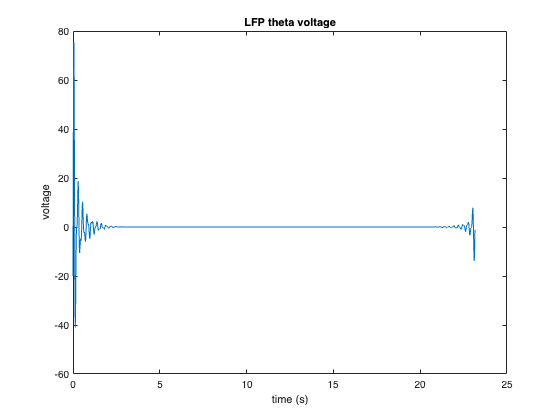

[visual_1_LFP_theta_voltage, visual_1_LFP_theta_phase] = visual("1, LFP").getBand([4,8]); %*% 채널 번호와 band 값을 수정합니다.

% time-voltage plot
plot(visual("1, LFP").t, visual_1_LFP_theta_voltage)
title('LFP theta voltage')
xlabel('time (s)')
ylabel('voltage')

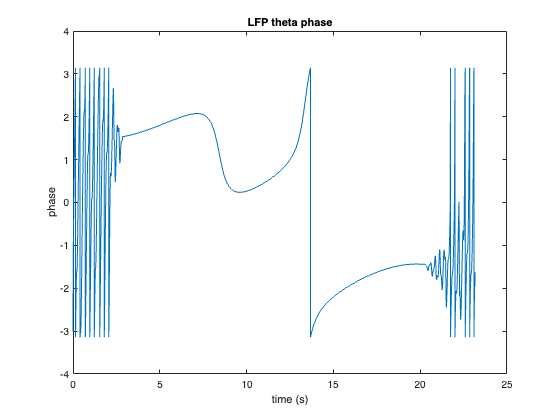

% time-phase plot
plot(visual("1, LFP").t, visual_1_LFP_theta_phase) %*% 채널 번호와 band 값을 수정합니다.
title('LFP theta phase')
xlabel('time (s)')
ylabel('phase')

# (3) Normalized power vs. frequency

## x 축 frequency/ y 축normalized power 인 그래프

**(method) getNormalizedSTFT**

 위에서 읽어온 데이터에 이동하 선생님 파일에서 normalized stft를 얻는 과정 적용하기 위해, 그 코드 내용을 함수로 만들었습니다. 만약 옵션을 바꿔야 할 경우(window size 등) getNormalizedSTFT.m 파일의 내용을 수정하면 됩니다.

**paramter 2개**

- `raw`: raw signal data

- `sf`: sampling frequency

**output 3개**

- `normalized_stft`: normalized STFT 데이터 (row가 frequency, column이 time에 해당)

- `F`: downsampled frequency

- `T`: downsampled time

아래 코드는 1번 채널부터 3개의 채널에 대해 그래프를 그립니다.

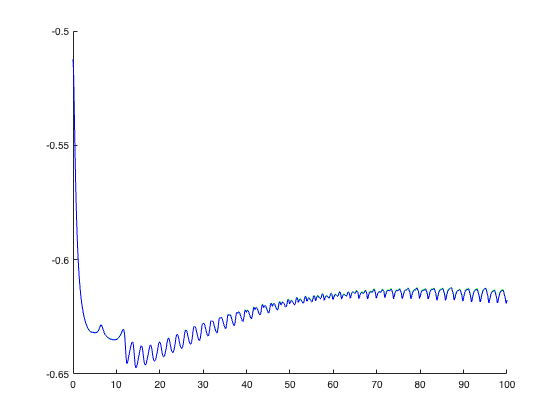

data_power = visual; %*% 데이터 저장하는 변수 이름 변경시 여기의 우변을 변경하세요
xlim_power = [0 100]; %*% frequency range
%
figure;
hold on;
colors = ["red", "green", "blue"]; %*% 채널 순서데로 색 지정
for i = [1,2,3] %*% 채널 번호
    channel_now = data_power(i + ", LFP");
    %raw_now = channel_now.raw; %*% band 지정하지 않고 진행할 경우
    [raw_now, ] = channel_now.getBand([4,8]); %*% 특정 band 데이터만 사용할 경우.
    sf_now = channel_now.sf;
    [normalized_stft, F, T] = getNormalizedSTFT(raw_now, sf_now);
    plot(F, mean(transpose(normalized_stft)), colors(i))
    xlim(xlim_power)
end
hold off;

## x 축 frequency/ y 축 **Normalized envelope** 인 그래프

주신 reference에 "Both the power spectral density and the coherence of field potentials were computed using the multi-taper method (MATLAB routines provided by K. Harris and G. Buzsaki)" 라고 되어 있는데, 아직 해당 matlab code를 찾지 못했습니다. 찾아낸 뒤 작업하겠습니다.			

## **Phase coherency **

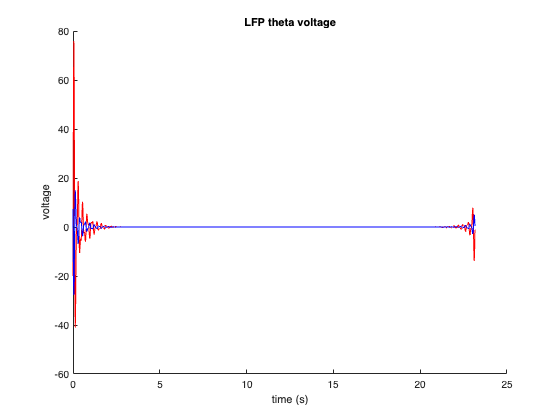

freqband = [4,8];
data_1 = visual("1, LFP"); %*% 채널 번호를 수정합니다
data_2 = visual("8, LFP"); %*% 채널 번호를 수정합니다


[data_1_voltage, data_1_phase] = data_1.getBand(freqband); 
[data_2_voltage, data_2_phase] = data_2.getBand(freqband);

% time-voltage plot
figure;
hold on;
plot(data_1.t, data_1_voltage, "red")
plot(data_2.t, data_2_voltage, "blue")
title('LFP theta voltage')
xlabel('time (s)')
ylabel('voltage')
hold off;

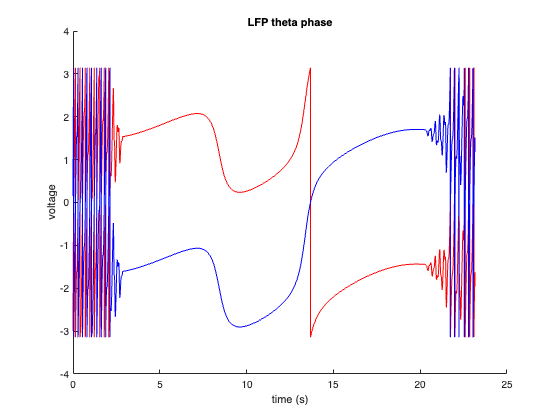

% time-voltage plot
figure;
hold on;
plot(data_1.t, data_1_phase, "red")
plot(data_2.t, data_2_phase, "blue")
title('LFP theta phase')
xlabel('time (s)')
ylabel('voltage')
hold off;

# **(4) Power band spectrum**

## **STFT plot**

특정 band만 보는 경우, 

- bandpass filter를 데이터에 먼저 적용하고 STFT를 만들어 plot을 그리는 방법

- filter를 적용하지 않고 STFT를 만든 뒤 y축에서 해당 band만 보여주는 방법 (김은지 선생님이 말씀하신 방법)

이 있을 것 같은데, 기존 이동하 선생님 파일에서 power plot을 그릴 때 2번을 사용했으므로, 2번으로 하면 될 것 같습니다.

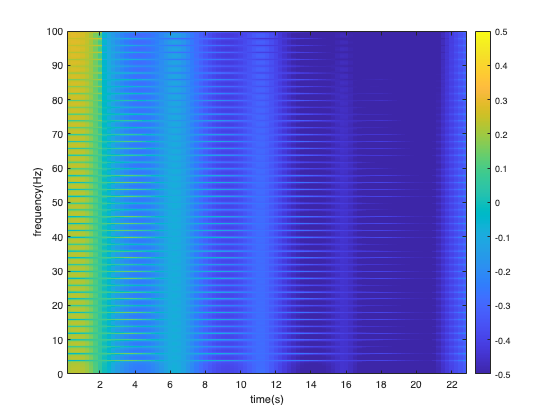

channel_now = visual("1, LFP"); %*% 채널 번호를 지정해 줍니다. 아래 코드는 모두 channel_now를 가지고 진행되므로 채널을 바꿀 땐 여기만 바꾸면 됩니다. %*%

raw_now = channel_now.raw; %get raw signal from the channel
sf_now = channel_now.sf; % get sampling frequency the channel
[normalized_stft, F, T] = getNormalizedSTFT(raw_now, sf_now); % get normalized stft

% 아래는 plot을 그리기 위한 코드로, 이동하 선생님 파일에 있는 내용 그대로입니다. 
%% apply averaging filter to draw a plot
PSF = fspecial('average',[2 16]); %set averaging filter with filter size [2 16]
Blurred_n = imfilter(normalized_stft,PSF,'conv'); % apply the filter         

%% draw the plot
imagesc((T(1:end)),F,Blurred_n,[-0.5 0.5]); 
ylim([0 100]) %*% 특정 band 부분만 보이게 할 때 여기를 조절하면 됩니다. %*%
axis xy
xlabel('time(s)'), ylabel('frequency(Hz)')
colorbar %color bar 추가하는 커맨드

## power plot

SFTF를 그리는 코드에서 averaging filter를 적용하는 부분까지의 코드만 사용하면 됩니다 (Blurred_n을 얻는 부분). 

각 band의 범위 값은 이동하 선생님 파일에 있는 그대로입니다.

channel_now = visual("1, LFP"); %*% 채널 번호를 지정해 줍니다. 아래 코드는 모두 channel_now를 가지고 진행되므로 채널을 바꿀 땐 여기만 바꾸면 됩니다. %*%

raw_now = channel_now.raw; %get raw signal from the channel
sf_now = channel_now.sf; % get sampling frequency the channel
[normalized_stft, F, T] = getNormalizedSTFT(raw_now, sf_now); % get normalized stft
PSF = fspecial('average',[2 16]); %set averaging filter with filter size [2 16]
Blurred_n = imfilter(normalized_stft,PSF,'conv'); % apply the filter 


band_bar = []; % band별 mean을 저장하는 array

alpha_find = find(F>8 & F<13); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
alpha_power = mean(Blurred_n(alpha_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(1) = mean(alpha_power);

beta_find = find(F>12 & F<33); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
beta_power = mean(Blurred_n(beta_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(2) = mean(beta_power);

theta_find = find(F>3.5 & F<8); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
theta_power = mean(Blurred_n(theta_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(3) = mean(theta_power);

delta_find = find(F>1 & F<3); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
delta_power = mean(Blurred_n(delta_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(4) = mean(delta_power);

gamma_find = find(F>25 & F<100); %*% band 값을 조절하려면 여기의 부등식을 수정하면 됩니다.
gamma_power = mean(Blurred_n(gamma_find,:)); %time 별로 mean 취함 (average out the frequency)
band_bar(5) = mean(gamma_power);


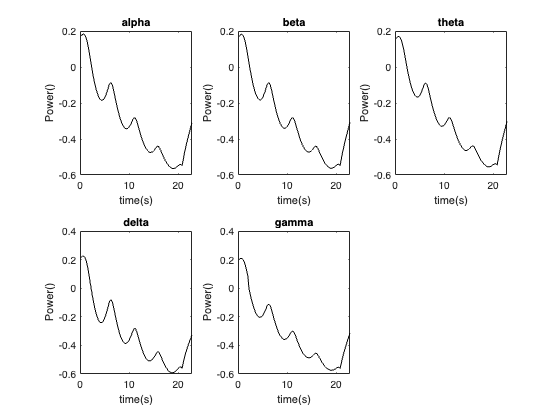

figure;

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.
subplot(2,3,1),plot(T,alpha_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('alpha')
subplot(2,3,2),plot(T,beta_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('beta')
subplot(2,3,3),plot(T,theta_power,'k');  
xlabel('time(s)'), ylabel('Power()'), title('theta')
subplot(2,3,4),plot(T,delta_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('delta')
subplot(2,3,5),plot(T,gamma_power,'k');   
xlabel('time(s)'), ylabel('Power()'), title('gamma')

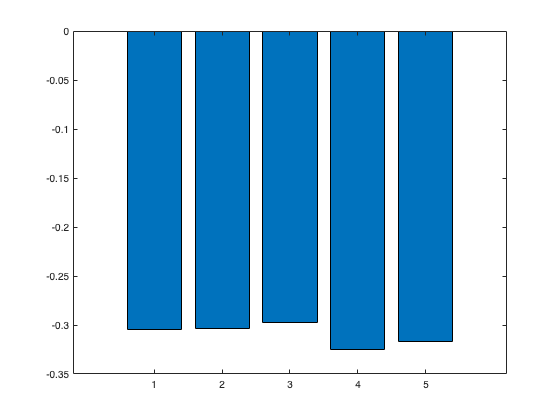


figure;
bar(band_bar)

# **(5) **Phase locking: Circular distribution and phase locking value (Phase-spike locking)

summary_multichannel 파일의 figure 2.k - 2.n에 있는 분석 내용을 새 데이터 포맷에서 수행할 수 있도록, 기존에 theta 기준으로 작성되어있던 함수를 모두 수정했습니다.

- Figure 2.k. theta waves and theta phase

- Figure 2.m.circular distrubution of theta phases(angles) at spikes per neuron

- Figure 2.n. distrubution of theta phases at spikes

- Uniform test(phase-locking detection)

visual("5, LFP")과 visual("4, SU"), 두 데이터를 가지고 진행하겠습니다. 

getBand 함수에 원하는 band를 입력합니다.

작업을 시작하기 전에 spike sorting을 먼저 합니다. �Spike 별로 그리는 그림이 있기 때문입니다.

                        %thres, preTime, postTime
visual("5, LFP").detectSpikes(1.3,2,2); % detect spikes

number of spikes found : 308


visual("5, LFP").getPCScores(); % do PCA 

visual("5, LFP").getKmeansClusters(3,2212323231); % do k-means on PC scores to sort the spikes

number of spikes per cluster:
cluaster 1: 70 
cluaster 2: 152 
cluaster 3: 86 


                %*%  frequency band를 변경합니다 
visual("5, LFP").getBand(    [4,8]      );


                        %thres, preTime, postTime
visual("4, SU").detectSpikes(5,2,2); % detect spikes

number of spikes found : 111


visual("4, SU").getPCScores(); % do PCA 

visual("4, SU").getKmeansClusters(3,2212323231); % do k-means on PC scores to sort the spikes

number of spikes per cluster:
cluaster 1: 28 
cluaster 2: 76 
cluaster 3: 7 


                %*%  frequency band를 변경합니다 
visual("4, SU").getBand(    [4,8]      );

### Figure 2.k (band waves and phase)

channel object에 **getBand **함수를 실행한 것을 (2)에서처럼 함수 output으로 바로 받아올 수도 있고, 여기에서처럼 channel 내부에 저장된 것을 불러올 수도 있습니다. 이 때 변수명은 아래와 같습니다.

- `.bandWave`: filtering 후 voltage

- `.bandPhase:` filtering 후 �phase  

figure
subplot(3,2,1)
p_raw = plot(visual("5, LFP").t, visual("5, LFP").raw); %raw trace plot
p_raw.Color = 'red'; %색깔 조절
hold on;

p_thetaWaves = plot(visual("5, LFP").t, visual("5, LFP").bandWave); %theta wave plot
p_thetaWaves.Color = 'blue'; %색깔 조절
legend("raw trace", "theta trace")
title("raw trace and theta trace: channel 5, LFP")
hold off;
subplot(3,2,3)
p_thetaPhases = plot(visual("5, LFP").t, visual("5, LFP").bandPhase);
p_thetaPhases.Color = 'blue'; %색깔 조절
title("theta phase unscaled: channel 5, LFP")

subplot(3,2,5)
p_thetaPhases = plot(visual("5, LFP").t, visual("5, LFP").bandPhase);
p_thetaPhases.Color = 'blue'; %색깔 조절
ylim([-30, 30]) % y축 스케일을 조절해 trace 모양이 잘 드러나게 하였음
title("theta phase with scaled y axis: channel 5, LFP")

subplot(3,2,2)
p_raw = plot(visual("4, SU").t, visual("4, SU").raw); %raw trace plot
p_raw.Color = 'red'; %색깔 조절
hold on;

p_thetaWaves = plot(visual("4, SU").t, visual("4, SU").bandWave); %theta wave plot
p_thetaWaves.Color = 'blue'; %색깔 조절
legend("raw trace", "theta trace")
title("raw trace and theta trace: channel 4, SU")
hold off;
subplot(3,2,4)
p_thetaPhases = plot(visual("4, SU").t, visual("4, SU").bandPhase);
p_thetaPhases.Color = 'blue'; %색깔 조절
title("theta phase unscaled: channel 4, SU")

subplot(3,2,6)
p_thetaPhases = plot(visual("4, SU").t, visual("4, SU").bandPhase);
p_thetaPhases.Color = 'blue'; %색깔 조절
ylim([-30, 30]) % y축 스케일을 조절해 trace 모양이 잘 드러나게 하였음
title("theta phase with scaled y axis: channel 4, SU")

### Figure 2.m (circular distrubution of theta phases at spikes per neuron)

figure 2.j와 비슷한 방식으로 사용

**phase 데이터 가져오는 method 이름**

- `channelobject.getBandPhaseByClusterNum(clusterNum)`

**circular histogram 그리는 matlab 함수(circstat 애드온 설치 필요): **`circ_plot`

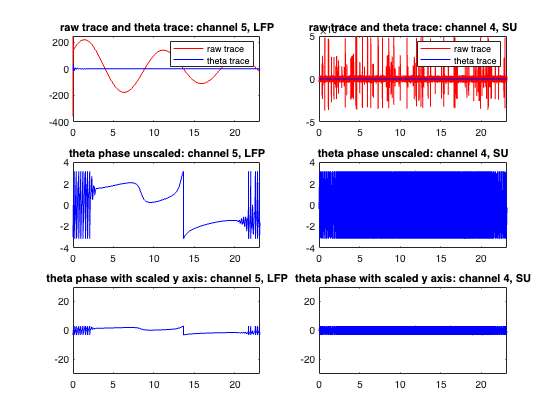

figure
subplot(3,2,1)
[phaseValues_1, nSpikes] = visual("5, LFP").getBandPhaseByClusterNum(1); %cluster 1의 phase 계산값 가져오기

circ_plot(phaseValues_1,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) + ":channel 5, LFP"); %subplot 제목 

subplot(3,2,3)
[phaseValues_2, nSpikes_2] = visual("5, LFP").getBandPhaseByClusterNum(2); %cluster 2의 phase 계산값 가져오기
circ_plot(phaseValues_2,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(2) + ', n = ' + string(nSpikes_2)+ ":channel 5, LFP" ); %subplot 제목 

subplot(3,2,5)
[phaseValues_3, nSpikes_3] = visual("5, LFP").getBandPhaseByClusterNum(3); %cluster 1의 phase 계산값 가져오기
circ_plot(phaseValues_3,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3)+ ":channel 5, LFP" ); %subplot 제목 



subplot(3,2,2)
[phaseValues_1, nSpikes] = visual("4, SU").getBandPhaseByClusterNum(1); %cluster 1의 phase 계산값 가져오기
circ_plot(phaseValues_1,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) + ":channel 4, SU"); %subplot 제목 

subplot(3,2,4)
[phaseValues_2, nSpikes_2] = visual("4, SU").getBandPhaseByClusterNum(2); %cluster 2의 phase 계산값 가져오기
circ_plot(phaseValues_2,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(2) + ', n = ' + string(nSpikes_2)+ ":channel 4, SU" ); %subplot 제목 

subplot(3,2,6)
[phaseValues_3, nSpikes_3] = visual("4, SU").getBandPhaseByClusterNum(3); %cluster 1의 phase 계산값 가져오기
circ_plot(phaseValues_3,'hist',[],20,true,false); %bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3)+ ":channel 4, SU" ); %subplot 제목 

sgtitle("figure 2.m. circular distrubution of theta phases(angles) at spikes") %전체 제목

### Figure 2.n. (distrubution of theta phases at spikes)

figure 2.m에서 사용한 데이터를 `histgoram` 함수에 적용하면 됨

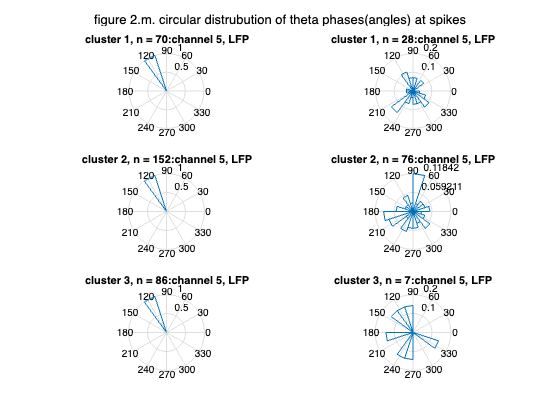

figure
subplot(3,2,1)
[phaseValues_1, nSpikes] = visual("5, LFP").getBandPhaseByClusterNum(1); %cluster 1의 phase 계산값 가져오기
h1 = histogram(phaseValues_1, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) + ":channel 5, LFP" ); %subplot 제목 
h1.FaceColor = "red"; %색상 지정

subplot(3,2,3)
[phaseValues_2, nSpikes_2] = visual("5, LFP").getBandPhaseByClusterNum(2); %cluster 2의 phase 계산값 가져오기
h2 = histogram(phaseValues_2, 20); % bin 개수 20개로 설정. 변경 가능

title('cluster ' + string(2) + ', n = ' + string(nSpikes_2) + ":channel 5, LFP" ); %subplot 제목 
h2.FaceColor = "blue"; %색상 지정

subplot(3,2,5)
[phaseValues_3, nSpikes_3] = visual("5, LFP").getBandPhaseByClusterNum(3); %cluster 1의 phase 계산값 가져오기
h3 = histogram(phaseValues_3, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3) + ":channel 5, LFP" ); %subplot 제목 
h3.FaceColor = "green"; %색상 지정





subplot(3,2,2)
[phaseValues_1, nSpikes] = visual("4, SU").getBandPhaseByClusterNum(1); %cluster 1의 phase 계산값 가져오기
h1 = histogram(phaseValues_1, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(1) + ', n = ' + string(nSpikes) + ":channel 4, SU" ); %subplot 제목 
h1.FaceColor = "red"; %색상 지정

subplot(3,2,4)
[phaseValues_2, nSpikes_2] = visual("4, SU").getBandPhaseByClusterNum(2); %cluster 2의 phase 계산값 가져오기
h2 = histogram(phaseValues_2, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(2) + ', n = ' + string(nSpikes_2) + ":channel 4, SU" ); %subplot 제목 
h2.FaceColor = "blue"; %색상 지정

subplot(3,2,6)
[phaseValues_3, nSpikes_3] = visual("4, SU").getBandPhaseByClusterNum(3); %cluster 1의 phase 계산값 가져오기
h3 = histogram(phaseValues_3, 20); % bin 개수 20개로 설정. 변경 가능
title('cluster ' + string(3) + ', n = ' + string(nSpikes_3) + ":channel 4, SU" ); %subplot 제목 
h3.FaceColor = "green"; %색상 지정

sgtitle("figure 2.n. distrubution of theta phases(angles) at spikes") %전체 제목

### Uniform test(phase-locking detection)

testing the non-uniformty of theta phase distribution using Rayleigh criterion to detect phase-locking.

We considered that phase-locking to theta waves happens for P-values below 0.05.

- phase-locking: theta wave의 특정 phase에서 spike가 유독 많이 일어나는 현상. Phase-locking이 없다면, spike에서의 theta angle분포는 uniform 분포를 따를 것. 따라서 theta angle 분포가 uniform distribution과 같은지 가설검정을 수행. 논문에서는 p-value 기준 0.05를 사용. 0.05보다 작으면 phase-locking. 0.05보다 크면 phase-locking 없는 것으로 판단.

**test 수행하는 함수 이름**

- **channelobject.uniformTest()**: cluster 순서대로 p-value 를 출력.

visual("5, LFP").uniformTest()
visual("4, SU").uniformTest()

# (6) **Phase-amplitude coupling (PAC)**

5번 채널을 low frequency로 두고 (4-8hz), 7번 채널을 high frequency로 둔다고 (40-80hz) 하고 예제를 진행하겠습니다. 아래와 같이 band filterting을 해줍니다.

                        %frequency range
visual("5, LFP").getBand([4,8]);
visual("7, LFP").getBand([40,80]);

3가지의 지표 모두 low frequency channel과 high frequency channel을 입력합니다. Mean vector length의 경우 high frequency 데이터의 amplitude를 normalize할지 말지를 추가로 입력하고,  modulation index의 경우는 phase angle 데이터를 discretize할 때 -2pi에서 2pi까지를 몇 개의 구간으로 나눌지를 입력해 줍니다.


%           low frequency     high frequency
getPLV(visual("5, LFP"), visual("7, LFP"))

%           low frequency     high frequency     direct? (noralize the amplitude)
%           
getMVL(visual("5, LFP"), visual("7, LFP"),       false)

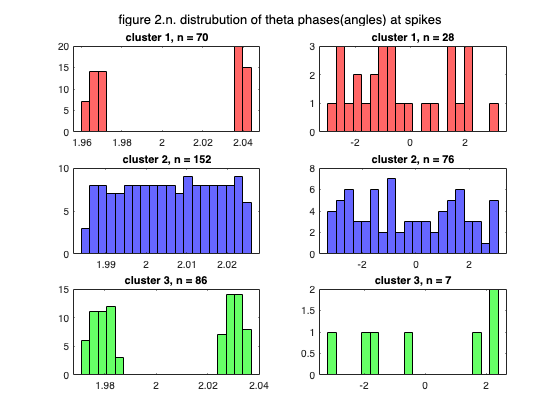

%           low frequency     high frequency    number of bins
%           

getMI(visual("5, LFP"), visual("7, LFP"),       10)

## (6.1) x axis – frequency for phase/ y axis – frequency for amplitude/ color scale: phase locking value or mean vector length or modulation index 인 그래프

- 이 그래프를 그리려면 구간 (e.g. [3,5] )이 아니라 특정 frequency (e.g. 5) 로 많은 횟수의 filtering을 해야 합니다. 

- 이 때 matlab의 bandpass 함수를 사용해 filtering하는 것은 부적절합니다. �저희 데이터처럼 frequency가 큰 데이터의 경우 한번 필터링 하는 데에 20초 이상 걸리고, 또 점이 아니라 구간으로 필터링하기 때문입니다.

- 그래서 complex morlet wavelet이라는 것을 대신 사용합니다.

- 이는 complex sine wave와 guassian function을 곱한 wavelet basis로 convolution을 계산하는 작업을 통해 filtering을 하는 방법입니다.

- 이때 gaussian function의 폭이 좁을수록 filtering이 세밀하게 진행되지만 대신 계산의 정확도가 떨어질 수 있습니다.

- 따라서 아래 코드에서 gaussian_bandwidth값을 조절하면서 bandpass로 필터링 한 결과와 그림이 비슷하게 나오는 gaussian_bandwidth 값을 먼저 찾아야 합니다.

%%%%%%%%%%%%%%%%%%%%%%%%%
gaussian_bandwidth = 12;

pvals = 1.0e-53 *

    0.2326
    0.0000
    0.0000


%%%%%%%%%%%%%%%%%%%%%%%%%

pvals =     0.5075
    0.6573
    0.6188


channel_test = visual("1, LFP");
frequency_test = 20;

signal_test        = channel_test.raw;
time_test          = channel_test.t;
srate_test         = channel_test.sf;
time_wavelet_low  = -1:(1/srate_test):1;
n_wavelet_test     = length(time_wavelet_low);
n_data_test        = channel_test.nTimestamps;
n_convolution_test = n_wavelet_test + n_data_test - 1;


ans = 0.6354

wavelet_gaussian_sd_test       = gaussian_bandwidth / (2 * pi * frequency_test);
wavelet_gaussian_height_test   = (wavelet_gaussian_sd_test * sqrt(pi))^(-1/2);
wavelet_gaussian_part_test     = wavelet_gaussian_height_test * exp(-time_wavelet_low .^ 2 ./ (2 * (wavelet_gaussian_sd_test^2)));
wavelet_complex_wave_part_test = exp(2 * 1i * pi * frequency_test .* time_wavelet_low);

ans = 0.0720

wavelet_test                   = wavelet_gaussian_part_test .* wavelet_complex_wave_part_test;

fft_signal_test           = fft(signal_test, n_convolution_test);
fft_wavelet_test          = fft(wavelet_test, n_convolution_test);

ans = 0.8579

convolution_result_test   = ifft(fft_signal_test.*fft_wavelet_test, n_convolution_test);
half_of_wavelet_size_test = (length(time_wavelet_low)-1)/2;
convolution_result_test   = convolution_result_test((half_of_wavelet_size_test+1):(end-half_of_wavelet_size_test));

figure
subplot(2,1,1)
plot(real(convolution_result_test))
subplot(2,1,2)
bandpass_filtered_test = bandpass(signal_test, [-1, 1] + frequency_test, srate_test);
plot(bandpass_filtered_test);

위 두 그림이 비슷하게 나오는 gaussian_bandwidth 값을 찾아야 합니다.

### 필터링

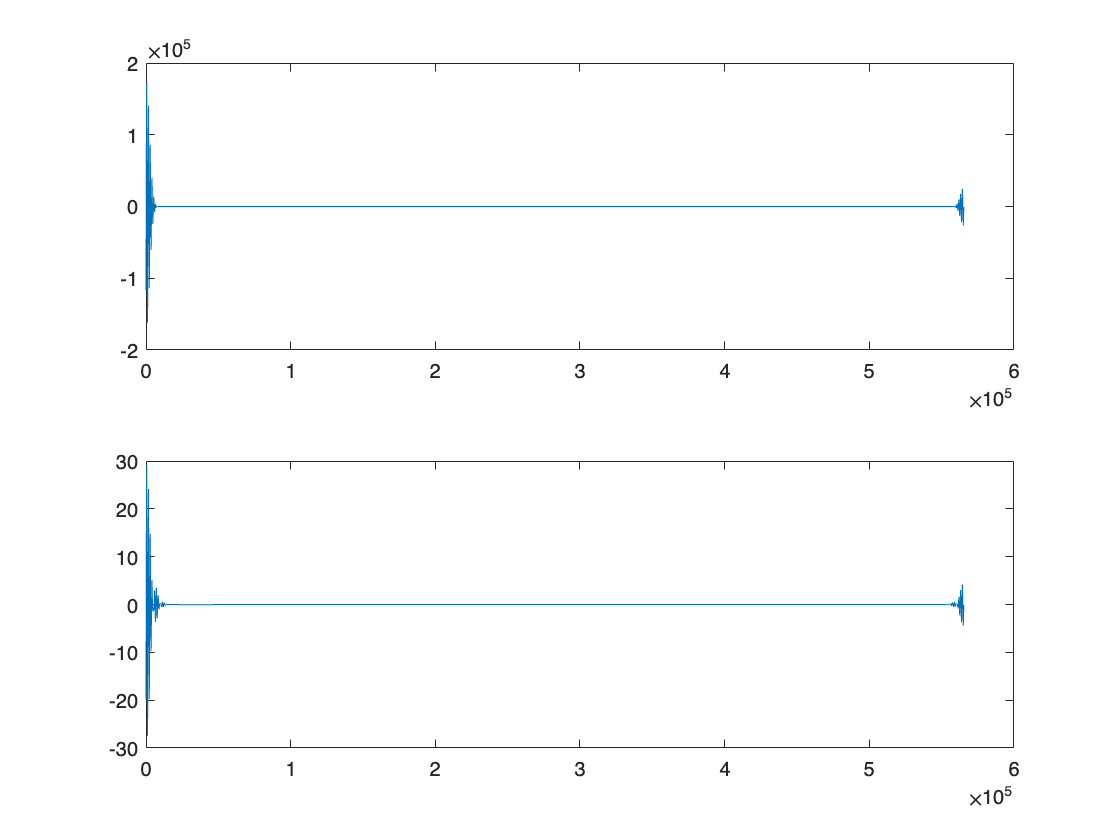

%%%%%%%%%%%%% THINGS TO CHANGE %%%%%%%%
gaussian_bandwidth = 12;
channel_now = visual("5, LFP");
freq_array_low    = 5:45; % Hz. 낮은 frequency list (phase)
freq_array_high    = 10:400; % Hz 높은 frequency list (amplitude)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% common parameters for both of low and high
time        = channel_now.t;
srate      = channel_now.sf;
time_wavelet = -1:(1/srate):1;
n_wavelet   = length(time_wavelet);
n_data  = channel_now.nTimestamps;
n_convolution = n_wavelet + n_data - 1;
half_of_wavelet_size = (n_wavelet-1)/2;
signal = channel_now.raw;
fft_signal = fft(signal, n_convolution);

tic
% signal for low

filtered_analytic_signal_low = zeros([length(freq_array_low), n_data]);
% loop for low
freq_array_now = freq_array_low;
for fi=1:length(freq_array_now)

    frequency_now = freq_array_now(fi);
    wavelet_gaussian_sd_now       = gaussian_bandwidth / (2 * pi * frequency_now);
    wavelet_gaussian_height_now   = (wavelet_gaussian_sd_now * sqrt(pi))^(-1/2);
    wavelet_gaussian_part_now     = wavelet_gaussian_height_now * exp(-time_wavelet .^ 2 ./ (2 * (wavelet_gaussian_sd_now^2)));
    wavelet_complex_wave_part_now = exp(2 * 1i * pi * frequency_now .* time_wavelet);
    wavelet_now                   = wavelet_gaussian_part_now .* wavelet_complex_wave_part_now;
    fft_wavelet_now         = fft(wavelet_now, n_convolution);
    convolution_result_now   = ifft(fft_signal .* fft_wavelet_now, n_convolution);
    convolution_result_now   = convolution_result_now((half_of_wavelet_size+1):(end-half_of_wavelet_size));
    filtered_analytic_signal_low(fi, :) = convolution_result_now;
end

% signal for low
filtered_analytic_signal_high = zeros([length(freq_array_high), n_data]);
% loop for low
freq_array_now = freq_array_high;
for fi=1:length(freq_array_now)
    frequency_now = freq_array_now(fi);
    wavelet_gaussian_sd_now       = gaussian_bandwidth / (2 * pi * frequency_now);
    wavelet_gaussian_height_now   = (wavelet_gaussian_sd_now * sqrt(pi))^(-1/2);
    wavelet_gaussian_part_now     = wavelet_gaussian_height_now * exp(-time_wavelet .^ 2 ./ (2 * (wavelet_gaussian_sd_now^2)));
    wavelet_complex_wave_part_now = exp(2 * 1i * pi * frequency_now .* time_wavelet);
    wavelet_now                   = wavelet_gaussian_part_now .* wavelet_complex_wave_part_now;
    fft_wavelet_now         = fft(wavelet_now, n_convolution);
    convolution_result_now   = ifft(fft_signal .* fft_wavelet_now, n_convolution);
    convolution_result_now   = convolution_result_now((half_of_wavelet_size+1):(end-half_of_wavelet_size));
    filtered_analytic_signal_high(fi, :) = convolution_result_now;
end
toc


### MI 계산

계산에 10분 가량 소요됩니다

% 
n_bin = 18;
MI_matrix = zeros([length(freq_array_high), length(freq_array_low)]);
tic
for fi_high=1:length(freq_array_high)
    for fi_low=1:length(freq_array_low)    
        MI_matrix(fi_high, fi_low) = getMI( ...
            filtered_analytic_signal_low(fi_low, :), ...
            filtered_analytic_signal_high(fi_high, :), ...
            n_bin ...
            );
    end
end
toc

## draw the plot

Elapsed time is 80.557562 seconds.


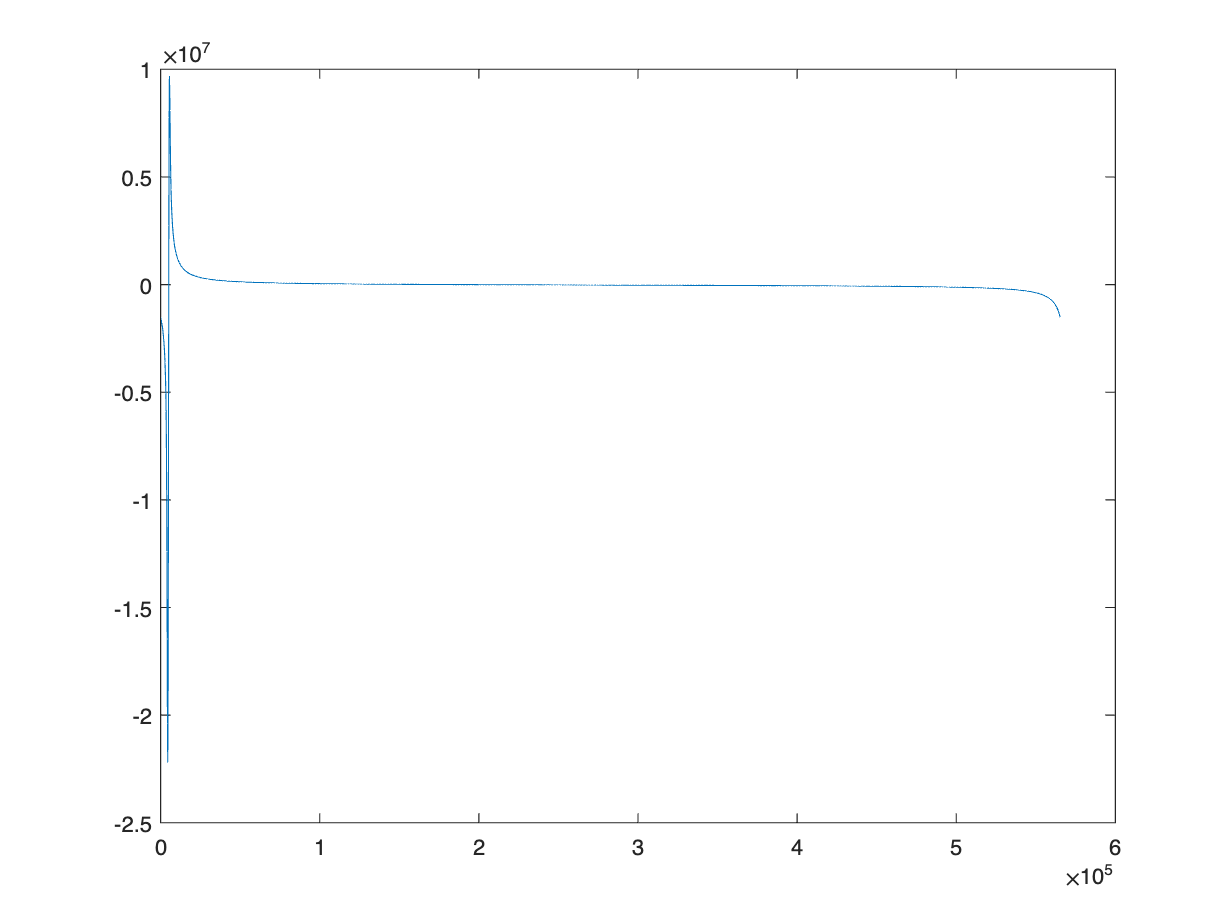

figure

contourf(freq_array_low,freq_array_high, MI_matrix, 40,'linecolor','none')
axis square
colorbar




### PLV 계산 및 그림 그리기

PLV_matrix = zeros([length(freq_array_high), length(freq_array_low)]);
tic
for fi_high=1:length(freq_array_high)
    for fi_low=1:length(freq_array_low)    
        PLV_matrix(fi_high, fi_low) = getPLV( ...
            filtered_analytic_signal_low(fi_low, :), ...
            filtered_analytic_signal_high(fi_high, :) ...
            );
    end
end
toc

Elapsed time is 451.580440 seconds.


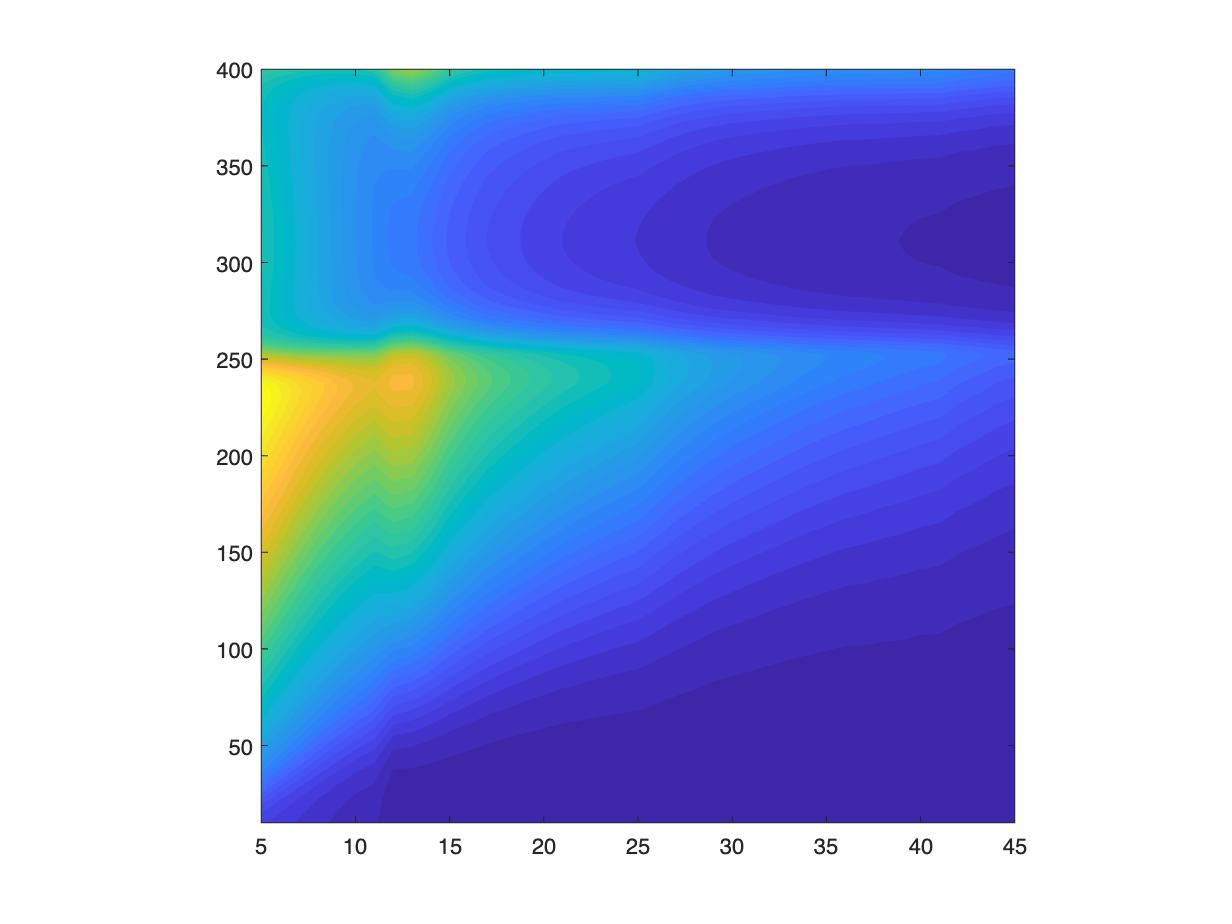

'contourcmap' requires Mapping Toolbox.


figure
contourf(freq_array_low,freq_array_high, PLV_matrix, 40,'linecolor','none')
axis square
contourcmap

colorbar

MVL_matrix = zeros([length(freq_array_high), length(freq_array_low)]);
tic
for fi_high=1:length(freq_array_high)
    for fi_low=1:length(freq_array_low)    
        MVL_matrix(fi_high, fi_low) = getMVL(filtered_analytic_signal_low(fi_low, :), filtered_analytic_signal_high(fi_high, :), true);            
    end
end
toc

figure
contourf(freq_array_low,freq_array_high, MVL_matrix, 40,'linecolor','none')
axis square
contourcmap
colorbar